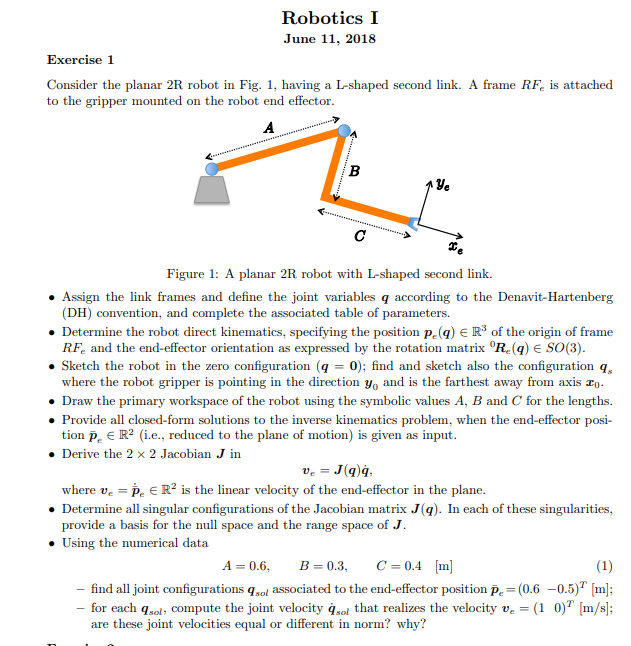

clear all, close all, clc
syms A B C D q1 q2 L
L_=0.4;
B_=0.3;
A_=0.4;
D_=sqrt(B_^2+A_^2);
syms alpha beta gamma
%[Rx Ry Rz] = getEulerRotationMatrices();
[Rz, R_set] = getRotMatProduct('Z',0,[ beta])

$$Rz = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & 0\\ \sin\left(\beta \right) & \cos\left(\beta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_set = 1×1 cell array
    {3×3 sym}


a1=A

$$a1 = A$$

a2=6

a2 = 6

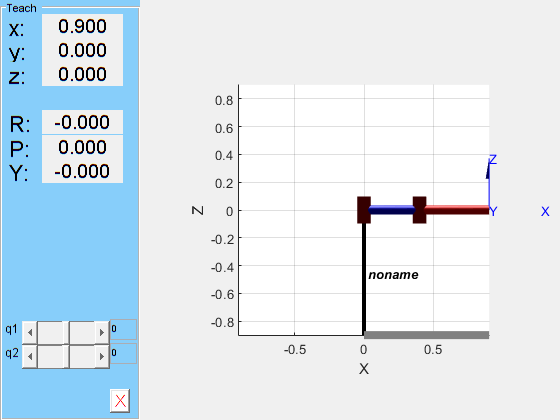

dhTable=[0,L,0,q1;
         0,D,0,q2];
% De Luca's approach
links = [
    Revolute('alpha', 0, 'a', L_ ,'d', 0);
    Revolute('alpha',  0, 'a', D_,'d', 0)

    ];
c600 = SerialLink(links);
c600.teach([0 0],'view','x')

[T_total T_Partial R_total R_Partial P_total P_Partial] = getTransformationMatrix(dhTable, 'alpha');
T_total %without translation

$$T\_total = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Az=[[Rz 0]',0]';
Az(end,end)=1;
T_total=simplify(T_total*Az)% with beta translation

$$T\_total = \left(\begin{array}{cccc} \cos\left(\beta +q_{1}+q_{2}\right) & -\sin\left(\beta +q_{1}+q_{2}\right) & 0 & \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \sin\left(\beta +q_{1}+q_{2}\right) & \cos\left(\beta +q_{1}+q_{2}\right) & 0 & \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%R_total=simplify(R_total*Rz)

p_e=T_total(1:3,4)

$$p\_e = \left(\begin{array}{c} \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

p_e2=simplify(P_Partial{1}+R_Partial{1}*P_Partial{2})

$$p\_e2 = \left(\begin{array}{c} \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

syms px real
syms py real

pehat=[px py]'

$$pehat = \left(\begin{array}{c} \mathrm{px}\\ \mathrm{py} \end{array}\right)$$

q_=solve(p_e2(1:2)==pehat)

q_ = struct with fields:
    q1: [2×1 sym]
    q2: [2×1 sym]


pehat_=[0 0]'

pehat_ =      0
     0


parametershat=[pehat;L;D]

$$parametershat = \left(\begin{array}{c} \mathrm{px}\\ \mathrm{py}\\ L\\ \text{D} \end{array}\right)$$

parametershat_=[pehat_;L_;D_]

parametershat_ =          0
         0
    0.4000
    0.5000



vpa(subs(q_.q1,parametershat,parametershat_))

$$ans = \left(\begin{array}{c} \mathrm{NaN}\\ \mathrm{NaN} \end{array}\right)$$

vpa(subs(q_.q2,parametershat,parametershat_))

$$ans = \left(\begin{array}{c} 3.1415926535897932384626433832795+0.22314355131420975576629509030983\,\mathrm{i}\\ -3.1415926535897932384626433832795-0.22314355131420975576629509030983\,\mathrm{i} \end{array}\right)$$